clc
clear all

load("rt40_mat_files\DOA_rt40.mat")
load("rt40_mat_files\pressure_rt40.mat")

[IR,fs] = audioread('IR.wav');
IR=IR(9500:9500+22000-1,1)

IR =     0.0000
    0.0000
   -0.0000
   -0.0001
    0.0000
    0.0001
    0.0000
   -0.0001
   -0.0001
   -0.0002


length(IR)

ans = 22000

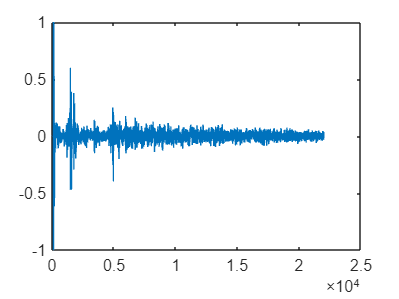

plot(IR)

sound(IR,fs)

P{1:12,1}(:,:) = IR(:,1)

P = 12×2 cell array
    {22000×1 double}    {22000×1 double}
    {22000×1 double}    {22000×1 double}
    {22000×1 double}    {22000×1 double}
    {22000×1 double}    {22000×1 double}
    {22000×1 double}    {22000×1 double}
    {22000×1 double}    {22000×1 double}
    {22000×1 double}    {22000×1 double}
    {22000×1 double}    {22000×1 double}
    {22000×1 double}    {22000×1 double}
    {22000×1 double}    {22000×1 double}
    {22000×1 double}    {22000×1 double}
    {22000×1 double}    {22000×1 double}


% Read stereo signal
S = audioread(['Measurements_Team4\594223__szegvari__battle-cinematic-soundtrack-music-atmo-background.wav']);
% Choose 10 seconds and resample
Sr = S(1:63.e3*10,:);%%Sr = resample(S(1:44.e3*10,:),480,441);


lspSetupNames = {'2.1','5.1','22.2','AALTO_24'};


% load default 5.1 setup and define some parameters with custom values
s = createSynthesisStruct('Binaural',true,...
    'DefaultArray',lspSetupNames{1},...
    'HRTFset',28,... % <---- CIPIC HRTF subject number
    'snfft',length(P{1}),...
    'fs',192e3,...
    'c',343);

createSynthesisStruct: User-defined settings are :
                fs: 192000
                 c: 343
    dimensionality: 2
             snfft: 22000
         showArray: 0
            Radius: 2
         LFEcutOff: 80
          Binaural: 1
           HRTFset: 28
                 g: [44000×10 double]
                f1: [10×1 double]
               Blp: [2.2371e-09 6.7112e-09 6.7112e-09 2.2371e-09]
               Alp: [1 -2.9948 2.9895 -0.9948]
               Bhp: [0.9974 -2.9922 2.9922 -0.9974]
               Ahp: [1 -2.9948 2.9895 -0.9948]
           lspLocs: [3×3 double]
        LFEchannel: 3
         hrtfindex: [3×1 double]
            hrir_l: [871×3 double]
            hrir_r: [871×3 double]



% You always need to define 'snfft'
%TODO: What RIRs/SIRs to use, demo works with ir_left and ir_right


%Synthesize the spatial impulse response with NLS as binaural
Hbin = cell(1,12);
   
for channel = 1:12
    [~, Hbin{channel}] = synthesizeSDMCoeffs(P{channel,1},DOA{channel,1}, s);
end

Started synthesizing
Started binaural synthesis.
Ended binaural synthesis in 0.0072763 seconds.
Ended synthesizing in 0.32648 seconds.
Started synthesizing
Started binaural synthesis.
Ended binaural synthesis in 0.0071948 seconds.
Ended synthesizing in 0.39816 seconds.
Started synthesizing
Started binaural synthesis.
Ended binaural synthesis in 0.0046073 seconds.
Ended synthesizing in 0.26639 seconds.
Started synthesizing
Started binaural synthesis.
Ended binaural synthesis in 0.0055743 seconds.
Ended synthesizing in 0.22912 seconds.
Started synthesizing
Started binaural synthesis.
Ended binaural synthesis in 0.0055293 seconds.
Ended synthesizing in 0.24156 seconds.
Started synthesizing
Started binaural synthesis.
Ended binaural synthesis in 0.0048252 seconds.
Ended synthesizing in 0.22573 seconds.
Started synthesizing
Started binaural synthesis.
Ended binaural synthesis in 0.0047125 seconds.
Ended synthesizing in 0.21857 seconds.
Started synthesizing
Started binaural synthesis.
Ended 

for channel = 1:12
    Hbin{1,channel} = resample(Hbin{1,channel},1,4);
end 
Y = zeros(size(Sr, 1), 2);
for channel = 1:2
    for position = 1:12
    % Check dimensions before fftfilt operation
    %disp(['Dimensions of Hbin{', num2str(channel), '}(:,1): ', num2str(size(Hbin{1,channel}(:, 1)))]);
    %disp(['Dimensions of Sr(:,', num2str(channel), '): ', num2str(size(Sr(:, channel)))]);
    
    % Convolution with Matlab's overlap-add
    Y(:,channel) = Y(:,channel) + fftfilt(Hbin{1,position}(:,channel), Sr(:, channel));
    end
end
    % Y contains the auralization of the spatial IRs with S


    % Y contains the auralization of the spatial IRs with S

    disp('Started Auralization');tic

Started Auralization


    savename = ['_Binaural_TEST.wav'];
    if max(abs(Y(:))) > 1
        Y = Y/max(abs(Y(:)))*.9;
        disp('Sound normalized, since otherwise would have clipped')
    end

Sound normalized, since otherwise would have clipped


    disp(['Ended Auralization in ' num2str(toc) ' seconds.'])

Ended Auralization in 0.013272 seconds.


    disp('Started writing the auralization wav file')

Started writing the auralization wav file


    disp([savename  ' on the disk.']);tic

_Binaural_TEST.wav on the disk.


    audiowrite(savename,Y/10,s.fs/4) % <---- save the result as wav
    info = audioinfo(savename);
    disp('Wrote ... ');

Wrote ... 


    disp(info)

             Filename: 'C:\Users\subas\Videos\RandD\github\SPAI\_Binaural_TEST.wav'
    CompressionMethod: 'Uncompressed'
          NumChannels: 2
           SampleRate: 48000
         TotalSamples: 630000
             Duration: 13.1250
                Title: []
              Comment: []
               Artist: []
        BitsPerSample: 16



    disp(['... in ' num2str(toc) ' seconds'])

... in 0.12615 seconds
